tic
%% types of bivariate gaussian

bi_norm = @(x, mu, S) (2*pi)^(-1)/sqrt(det(S))*exp(-1/2*(x-mu)'*inv(S)*(x-mu));

[X, Y] = meshgrid(linspace(-1,1,100));
mu = [0; 0];

s11 = 3;
s12 = 1.27;
s22 =2.59;

S1 = [s11,s12;s12,s22]

S1 =     3.0000    1.2700
    1.2700    2.5900



[V,D] = eig(S1);
eig_vals = diag(D)

eig_vals =     1.5086
    4.0814


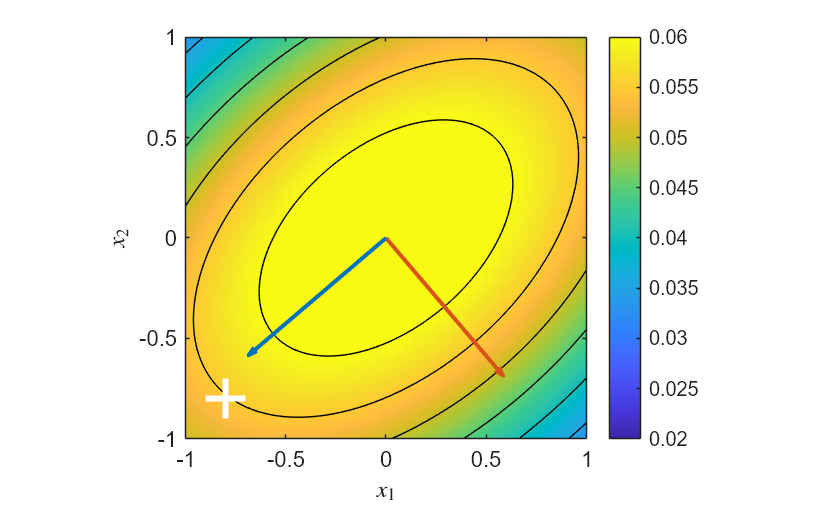


z1 = zeros(100,100);

for i = 1:100
    for j = 1:100
        x = [X(i,j); Y(i,j)];
        z1(i,j) = bi_norm(x, mu, S1);
    end
end

figure;
imagesc(linspace(-1,1,100), linspace(-1,1,100), z1);
clim([0.02, 0.06])
axis([-1, 1, -1, 1])
hold on;
contour(linspace(-1,1,100), linspace(-1,1,100), z1,'color','k')
plot(-0.8, -0.8, 'w+','markersize',20,'linewidth',3)
set(gca,'ydir','normal')
colorbar;
xlabel('$x_1$','interpreter','latex')
ylabel('$x_2$','interpreter','latex')
set(gca,'fontsize',11)
axis square

quiver(0,0, V(1,1), V(2,1),'color',[0.85, 0.325, 0.098],'linewidth',2);
quiver(0,0, V(1,2), V(2,2),'color',[0, 0.4470, 0.7410],'linewidth',2);

toc

Elapsed time is 0.746256 seconds.
